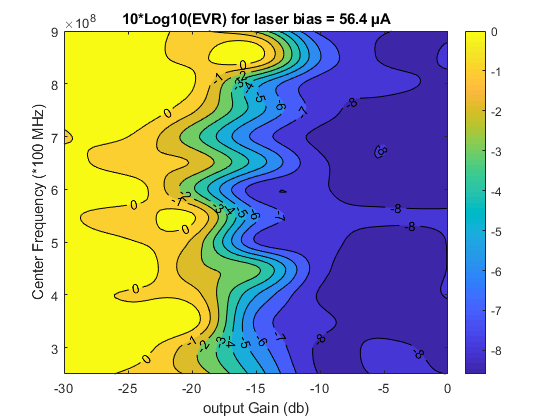

%courant bias%
courant_bias = 56.4; %(µA)%

minGain = -30; %minimum transmited power gain (in db)
maxGain =  0; %maximum transmited power gain (in db)
padGain = 5;   %measure pad for gains
numMeasurmentsGain = (abs(minGain) - abs(maxGain))/padGain;

minCarrierFrequency =  2.5e8; %minimum center frequency supported by adalm pluto (in hz)
maxCarrierFrequency =  9e8; %maximum centr frequency supported by the laser (in hz)
padCarrierFrequency =  50000e3; %pad of 10 khZ
numMeasurementsFreq = (maxCarrierFrequency-minCarrierFrequency)/padCarrierFrequency;
AverageError_function_Gain_CarrierFrequency = zeros(numMeasurementsFreq,numMeasurmentsGain);
Ber_function_Gain_CarrierFrequency = zeros(numMeasurementsFreq,numMeasurmentsGain);

x = minGain : padGain : maxGain;
y = minCarrierFrequency : padCarrierFrequency : maxCarrierFrequency;

% 0.7071 - 0.7071i
data_EVR_qam = [1.28668998400991,0.943003477784965,0.750760529512790,0.359868495817725,0.155812690067524,0.162069551787320,0.158167673936861;
    1.14455538870994,1.18714516183237,0.691612915484819,0.287464367988018,0.152549824863527,0.165396332655013,0.143283335890140;
    1.21283277036007,1.24218960715407,1.14706426756929,0.240040685455994,0.167659495029795,0.143614613173275,0.139865926184329;
    1.16792166228913,0.968159248707415,0.882389537462175,0.321441450267402,0.154504139146963,0.144104586752615,0.161225576522341;
    1.11368551898564,1.32746885727501,0.684568601074967,0.525775375798711,0.173713265763559,0.141941216847546,0.159448426700479;
    1.18135015165533,1.02644667087464,0.763810712523426,0.196515692226596,0.170244731295341,0.144262186021427,0.159575832622678;
    1.10174403426274,0.878293385018148,1.03644582269553,0.264735795160336,0.170928682583555,0.164461166718372,0.161809211386819;
    1.20314960129714,1.21210703163147,0.522346653858931,0.175974998890708,0.161577667440129,0.141665304790619,0.146853042906854;
    1.20968535331870,0.831824060462707,0.781133742089896,0.362914019748633,0.165249460332983,0.156859432105656,0.141458975478750;
    0.960069589835727,1.00217030046404,0.548809539569271,0.233523011830965,0.149736422235746,0.157038185983788,0.145124237008161;
    1.21574682142963,1.22769401528436,0.834046348425297,0.354590745184550,0.177160668282567,0.143880178298705,0.139626610646792;
    1.09832075957039,1.14299068509037,1.03263869041586,0.345548935026740,0.175230306748084,0.171714175247331,0.143793222036821;
    1.26352056034100,1.16117038964462,0.943531892967274,1.11421830360753,0.254744674169454,0.154148484769846,0.167458612637744;
    1.20537105192157,1.28260530835516,0.858681566830887,0.594876412839322,0.182978640716298,0.160713002496307,0.142901260378265];

data_ber_qam = [0.300034340700000,0.209010989000000,0.118708791200000,0.0198076923000000,0,0.000851648400000000,0;
    0.293791208800000,0.227912087900000,0.104917582400000,0.0116483516000000,0,0.000659340700000000,0;
    0.284835164800000,0.232829670300000,0.100741758200000,0.00629120880000000,0.00203296700000000,0,0;
    0.279258241800000,0.226868131900000,0.118873626400000,0.0176098901000000,0,0,5.49451000000000e-05;
    0.296450260300000,0.242335164800000,0.0954670330000000,0.0286263736000000,0.00384615380000000,0,0.000192307700000000;
    0.280714285700000,0.227747252700000,0.0805219780000000,0.00197802200000000,0.00162087910000000,0,0;
    0.280802530800000,0.177582417600000,0.141510989000000,0.00972527470000000,0.00203296700000000,0.000521978000000000,2.74725000000000e-05;
    0.265412087900000,0.175741758200000,0.0526098901000000,0.00288461540000000,0.000192307700000000,0,0;
    0.251923076900000,0.167032967000000,0.0779945055000000,0.0137912088000000,0.00142857140000000,0.000659340700000000,0;
    0.228406593400000,0.158571428600000,0.0601923077000000,0.00673076920000000,0,0.000219780200000000,0;
    0.299700299700000,0.248983516500000,0.145439560400000,0.0196703297000000,0.00491758240000000,0,0;
    0.299761108500000,0.246016483500000,0.151208791200000,0.0206318681000000,0.00228021980000000,0.009197802200000,0;
    0.380090497700000,0.285956182200000,0.200329670300000,0.166428571400000,0.00824175820000000,0,0.00126373630000000;
    0.335475844900000,0.272417582400000,0.171538461500000,0.0739560440000000,0.00423076920000000,0.000467033000000000,0];

figure (1)
z1 = 10*log10(data_EVR_qam);
%z1(isinf(-z1)) = -5.1;
[Xq,Yq] = ndgrid(minGain:(padGain/10):maxGain,...
    minCarrierFrequency:(padCarrierFrequency/10):maxCarrierFrequency);
% Vq = F(Xq,Yq);
Vq = interp2(x,y,z1,Xq,Yq,'cubic');
contourf(Xq,Yq,Vq,[-11 -10 -9.5 -9 -8 -7 -6 -5 -4 -3 -2 -1 0],'ShowText','on');
colorbar 
title('10*Log10(EVR) for laser bias = 56.4 µA');
xlabel('output Gain (db)');
ylabel('Center Frequency (*100 MHz)');

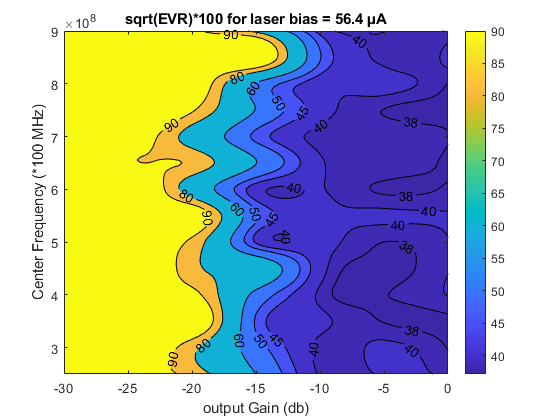


figure (2)
z2 = sqrt(data_EVR_qam)*100;
%z1(isinf(-z1)) = -5.1;
[Xq,Yq] = ndgrid(minGain:(padGain/10):maxGain,...
    minCarrierFrequency:(padCarrierFrequency/10):maxCarrierFrequency);
% Vq = F(Xq,Yq);
Vq = interp2(x,y,z2,Xq,Yq,'cubic');
contourf(Xq,Yq,Vq,[90 80 60 50 45 40 38 36],'ShowText','on');
colorbar 
title('sqrt(EVR)*100 for laser bias = 56.4 µA');
xlabel('output Gain (db)');
ylabel('Center Frequency (*100 MHz)');

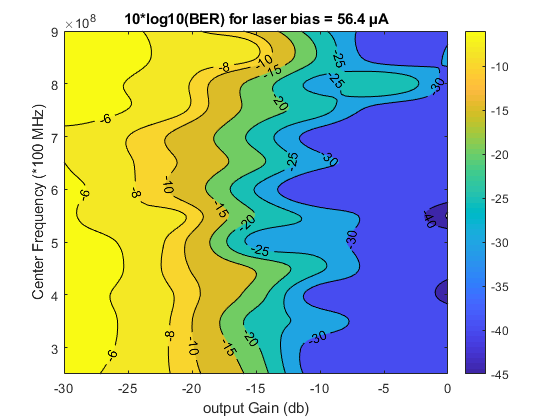


figure (3)
z3 = 10*log10(data_ber_qam);
z3(isinf(-z3)) = -33.1;
[Xq,Yq] = ndgrid(minGain:(padGain/10):maxGain,...
    minCarrierFrequency:(padCarrierFrequency/10):maxCarrierFrequency);
% Vq = F(Xq,Yq);
Vq = interp2(x,y,z3,Xq,Yq,'cubic');
contourf(Xq,Yq,Vq,[-45 -40 -30 -25 -20 -15 -10 -8 -6 -4],'ShowText','on');
colorbar 
title('10*log10(BER) for laser bias = 56.4 µA');
xlabel('output Gain (db)');
ylabel('Center Frequency (*100 MHz)');